# Class 7

Mapping and coordinates

% safety first
close all;
clear all;

% import library
addpath ~/Documents/m_map

% access NCEP reanalysis
! ~/opt/anaconda3/bin/ncdump -h air.2m.gauss.2020.nc

/bin/bash: /Users/takamitsu3/opt/anaconda3/bin/ncdump: No such file or directory


% get coordinates
filename="air.2m.gauss.2020.nc";
lon=ncread(filename,'lon'); % longitude
lat=ncread(filename,'lat'); % latitude
% get 2m air temperature data
air=ncread(filename,'air'); % air temperature

#### Let's plot it contourf

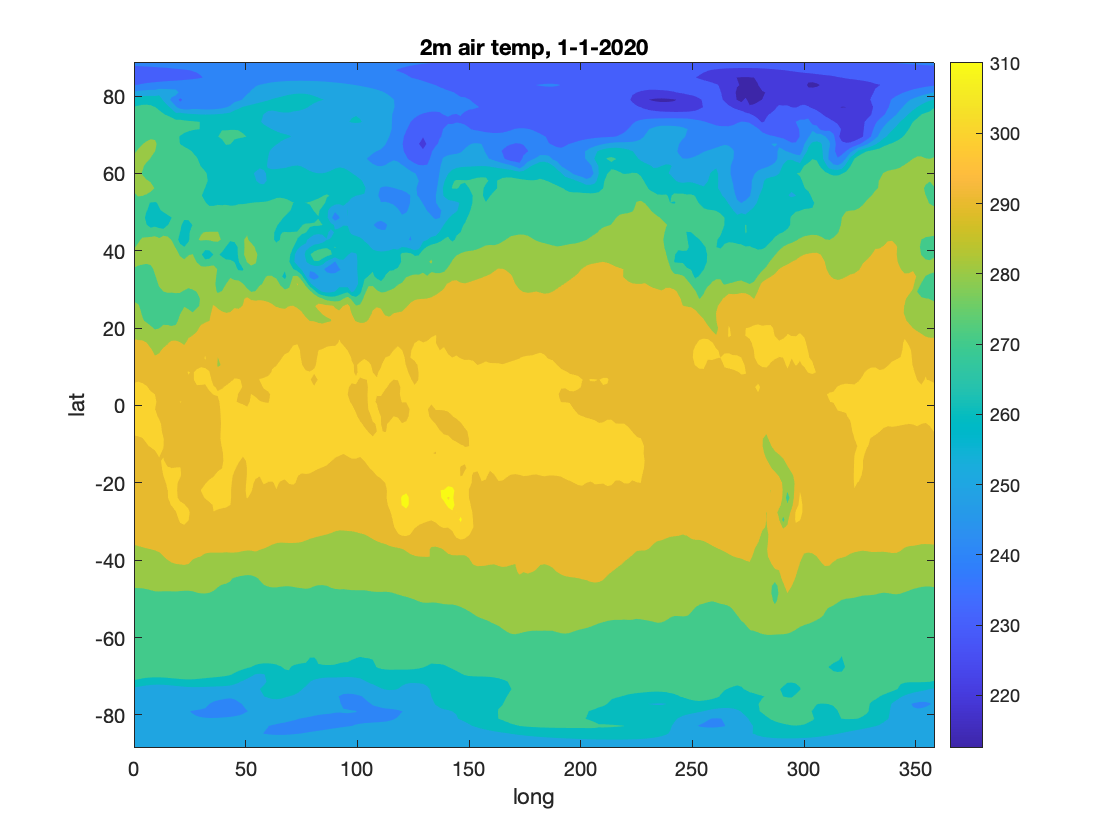

figure;
contourf(lon,lat,air(:,:,1)','edgecolor','none');
xlabel('long');
ylabel('lat');
colorbar;
title('2m air temp, 1-1-2020');

#### Plot over the North Pole using Azimuthal projection (Stereographic)

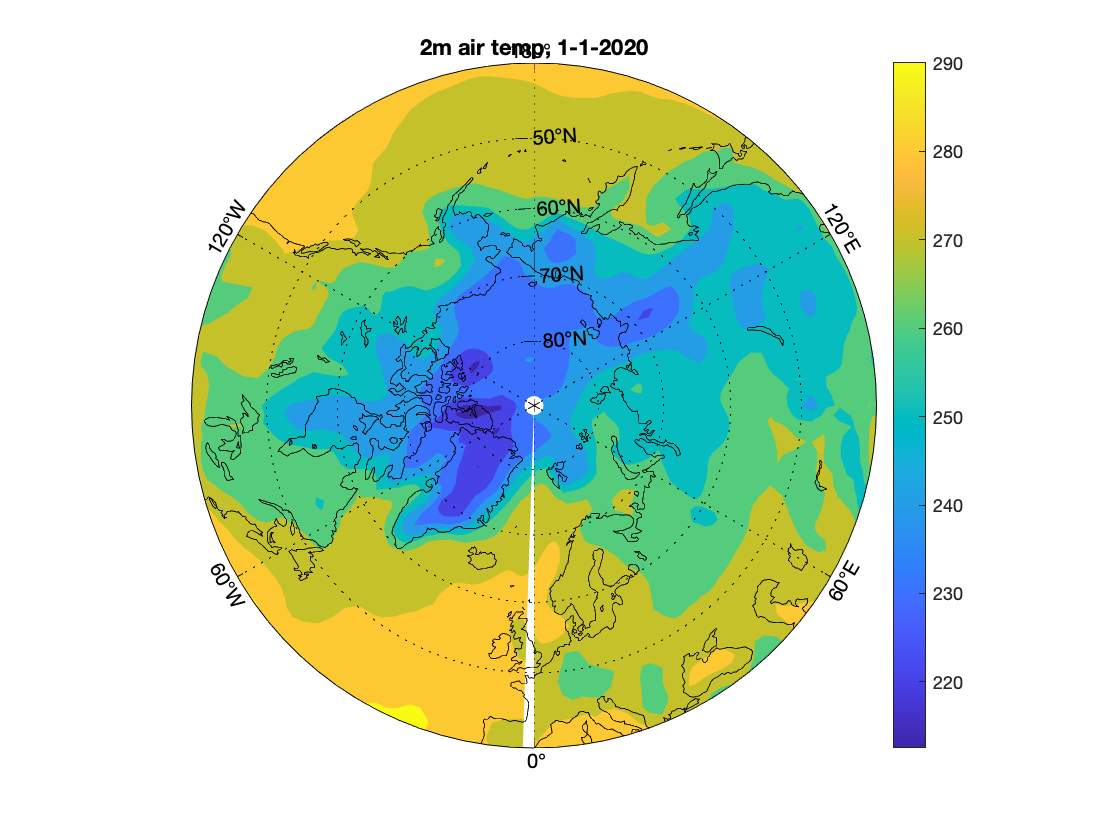

figure;
m_proj('Stereographic','lat',90,'radius',50);
m_contourf(lon,lat,air(:,:,1)','edgecolor','none');
m_coast('color','k');
m_grid;
title('2m air temp, 1-1-2020');
colorbar;

#### Fix the gap at 0° meridian

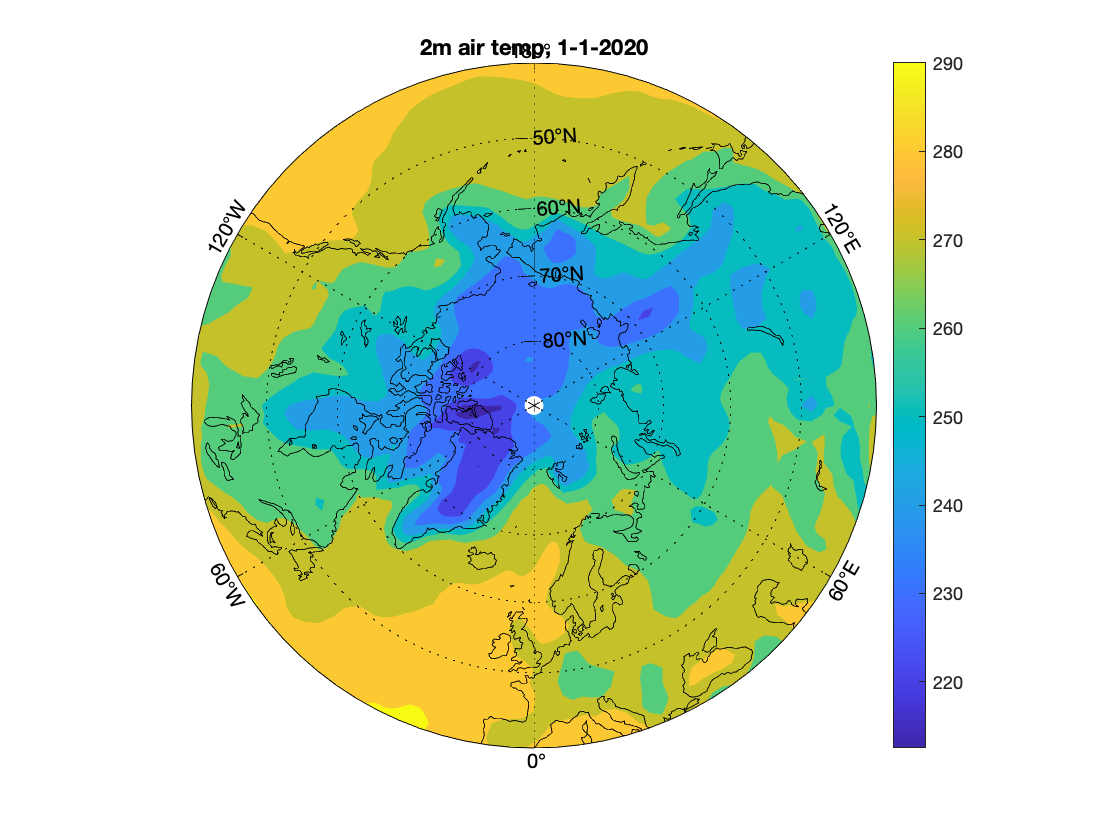

lon(end+1)=360;      % add one more longitude point
air(end+1,:,:)=air(1,:,:);  % repeat the data to wrap around the globe
figure;
m_proj('Stereographic','lat',90,'radius',50);
m_contourf(lon,lat,air(:,:,1)','edgecolor','none');
m_coast('color','k');
m_grid;
title('2m air temp, 1-1-2020');
colorbar;

#### Plot over the South Pole

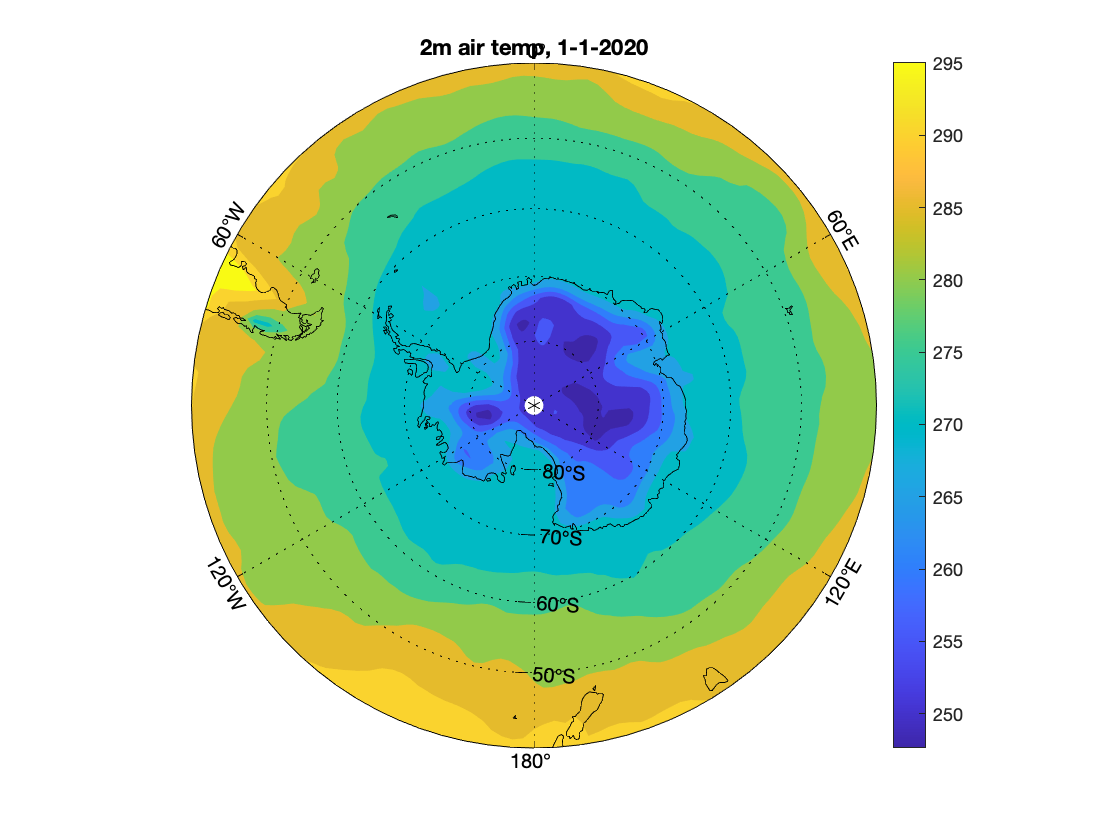

figure;
m_proj('Stereographic','lat',-90,'radius',50);
m_contourf(lon,lat,air(:,:,1)','edgecolor','none');
m_coast('color','k');
m_grid('Xaxislocation','top');
title('2m air temp, 1-1-2020');
colorbar;

#### Robinson projection for global map

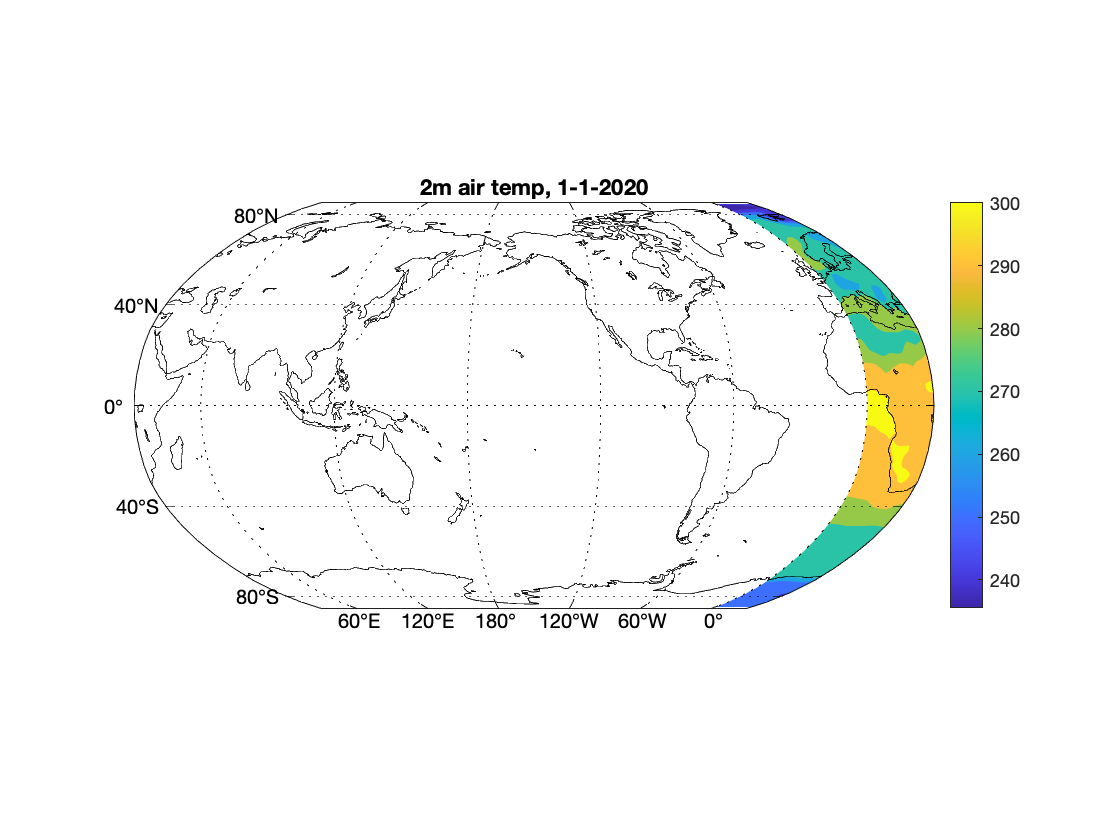

figure;
m_proj('Robinson','clon',-150);
m_contourf(lon,lat,air(:,:,1)','edgecolor','none');
m_coast('color','k');
m_grid;
title('2m air temp, 1-1-2020');
colorbar;

#### Robinson projection for global map

Need to plot twice to wrap around the globe

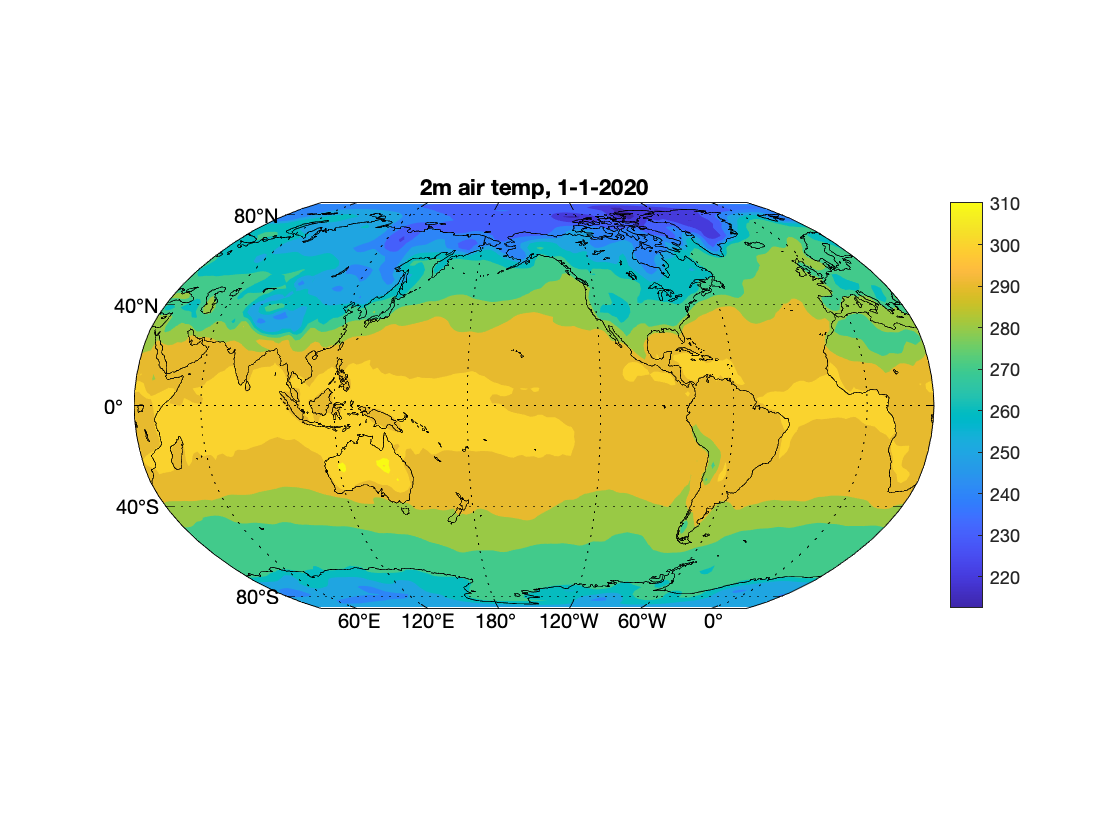

figure;
m_proj('Robinson','clon',-150);
m_contourf(lon,lat,air(:,:,1)','edgecolor','none');
hold on;
m_contourf(lon-360,lat,air(:,:,1)','edgecolor','none');
m_coast('color','k');
m_grid;
hold off;
title('2m air temp, 1-1-2020');
colorbar;

#### ETOPO2v2

2 minute global topographic map

! ~/opt/anaconda3/bin/ncdump -h ETOPO2v2c_f4.nc

/bin/bash: /Users/takamitsu3/opt/anaconda3/bin/ncdump: No such file or directory


x=ncread('ETOPO2v2c_f4.nc','x');
y=ncread('ETOPO2v2c_f4.nc','y');
z=ncread('ETOPO2v2c_f4.nc','z');

#### Oblique Mercator for US west coast topography

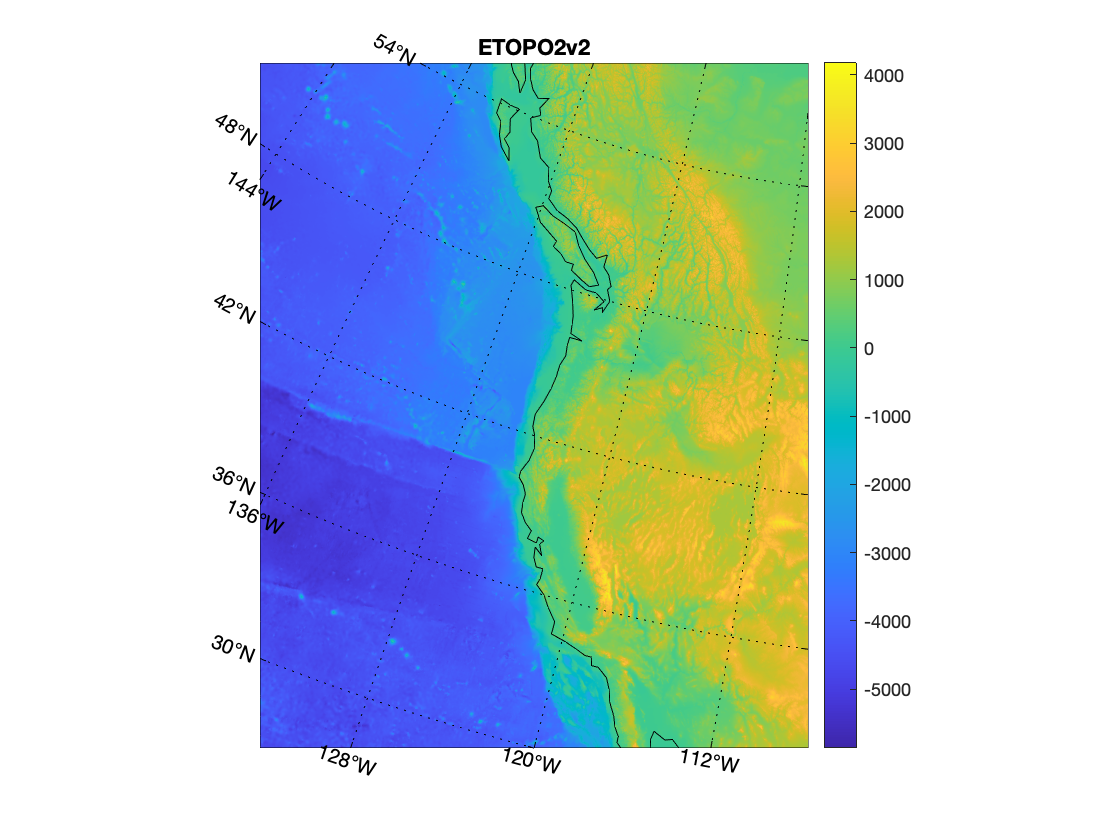

figure;
xr=(x>-160)&(x<-100);
yr=(y>20)&(y<60);
m_proj('oblique','lat',[56 30],'lon',[-132 -120],'aspect',.8);
m_pcolor(x(xr),y(yr),z(xr,yr)','edgecolor','none');
m_coast('color','k');
m_grid;
title('ETOPO2v2');
colorbar;

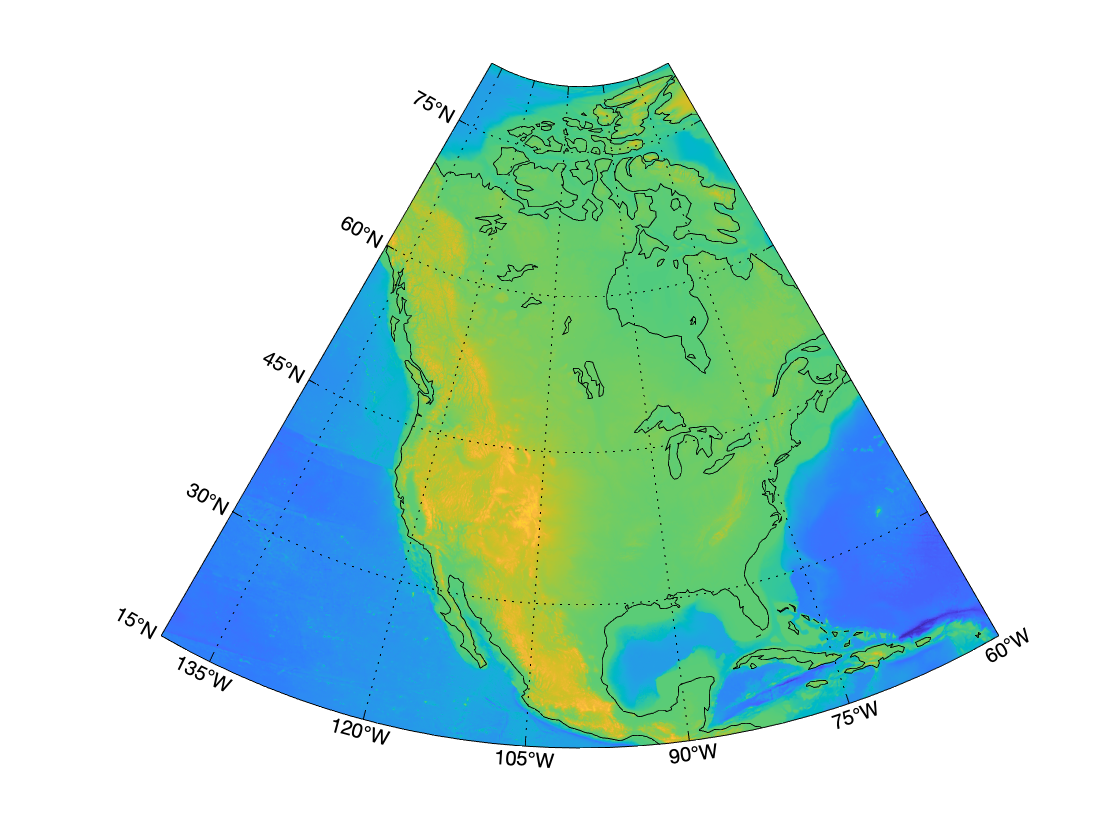

% Conic over the North America
figure;
xr=(x>-160)&(x<-50);
yr=(y>10)&(y<86);
m_proj('Albers Equal-Area Conic','lat',[15 85],'lon',[-140 -60]);
m_pcolor(x(xr),y(yr),z(xr,yr)','edgecolor','none');
m_coast('color','k');
m_grid;